%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end

t =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


reps = 20; % need more than 10 reps. 10 reps takes 15 min

Q_orig = 1e6;
Q = Q_orig / heterodyning_ratio;

band_width = f_a / Q % or f_a_original / Q_orig

band_width = 483.5590


T = 10e-3;

tau = 0.0143e-3;

w_mult = 3.5;
f_0s = linspace(f_a - w_mult*band_width, f_a + w_mult*band_width, 24);
L_f0s = length(f_0s);

dynamic_powers = zeros(reps, L_f0s);
static_powers  = zeros(reps, L_f0s);

start_secs = 0.0015;
assert(start_secs < t(end)/3);
start = round(start_secs * f_sampling);

done = 0;
num_runs = reps * L_f0s

num_runs = 480

tic

for l = 1 : reps
    f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q * Q_orig);
    noise_power = calculate_noise_power(f_sampling, T);
    noise = generate_thermal_noise(t, noise_power);
    p_s = bandpower(signal);
    p_n = bandpower(noise);
    
%     noise_resonated  = resonator_2(noise, f_0s(1),   band_width, f_sampling);
%     noise_resonated2 = resonator_2(noise, f_0s(end), band_width, f_sampling);
%     power_just_noise  = bandpower(noise_resonated (start:end))
%     power_just_noise2 = bandpower(noise_resonated2(start:end))
    
    parfor i = 1 : L_f0s
        f_0 = f_0s(i);

        limiting_band = [f_0-band_width, f_0+band_width];

        [f_iwave, signal_dynamic] = do_iwave_and_resonator(t, noise, signal, f_0, band_width, f_sampling, limiting_band, tau);
        signal_static = resonator_2(noise + signal, f_0, band_width, f_sampling);

        dynamic_powers(l, i) = bandpower(signal_dynamic(start:end));
        static_powers (l, i) = bandpower(signal_static (start:end));
    end
    done = done + L_f0s;
    frac_done = done/num_runs;
    timer_elapsed = toc;
    time_total = timer_elapsed / frac_done;
    time_remaining = time_total - timer_elapsed;
    fprintf('done %d%%, %d min gone, %d min rem\n', round(100*frac_done), round(timer_elapsed/60), round(time_remaining/60))
    
end

done 5%, 2 min gone, 47 min rem
done 10%, 5 min gone, 45 min rem
done 15%, 7 min gone, 42 min rem
done 20%, 10 min gone, 40 min rem
done 25%, 12 min gone, 37 min rem
done 30%, 15 min gone, 35 min rem
done 35%, 17 min gone, 32 min rem
done 40%, 20 min gone, 30 min rem
done 45%, 22 min gone, 27 min rem
done 50%, 25 min gone, 25 min rem
done 55%, 27 min gone, 22 min rem
done 60%, 30 min gone, 20 min rem
done 65%, 32 min gone, 17 min rem
done 70%, 35 min gone, 15 min rem
done 75%, 37 min gone, 12 min rem
done 80%, 40 min gone, 10 min rem
done 85%, 42 min gone, 7 min rem
done 90%, 44 min gone, 5 min rem
done 95%, 47 min gone, 2 min rem
done 100%, 49 min gone, 0 min rem



save('data/SNR_moving_across_band.mat', 'dynamic_powers', 'static_powers', 'f_0s')

dynamic_power = mean(dynamic_powers, 1);
static_power  = mean(static_powers,  1);
dynamic_power_err = std(dynamic_powers, 1);
static_power_err  = std(static_powers,  1);

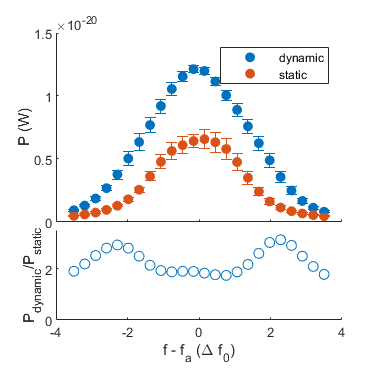

adstyle(8, 8)
tiledlayout(3,1, 'TileSpacing','tight')

nexttile([2, 1])
c = colororder;
df = f_a / Q;
scatter((f_0s-f_a)/df, dynamic_power, [], c(1,:), 'filled')
hold on
scatter((f_0s-f_a)/df, static_power,  [], c(2,:), 'filled')
errorbar((f_0s-f_a)/df, dynamic_power, dynamic_power_err/2, 'color',c(1,:), 'LineStyle','none', 'HandleVisibility',"off")
errorbar((f_0s-f_a)/df, static_power,  static_power_err/2,  'color',c(2,:), 'LineStyle','none', 'HandleVisibility',"off")
legend('dynamic', 'static')%, 'Location',"best") might get away with legend cause of the eps stretching when you put it into thingy
ylabel('P (W)')
xticklabels([])
xlim([-4 4])

nexttile
scatter((f_0s-f_a)/df, dynamic_power./static_power)
%y_lim = ylim();
%ylim([0, y_lim(2)])
ylabel('P_{dynamic}/P_{static}')
xlim([-4 4])
ylim([0 3.5])

xlabel('f - f_a (\Delta f_0)')